## Question 1

% Definition of constants
kt = 9.5;
kb = 0.0704;
j = 0.0058;
area = 51;
R = 10;

% Definition of SSR matrices A,B,C, and D.
A = [0 1 0; 0 (kt*kb)/(-2*R*j) 0; (82/area) 0 (-51/area)];
B = [0; (50*kt)/(2*R*j); 0];
C = [0 0 1];
D = 0;

% Definition of the main system
sys = ss(A, B, C, D);

### Requirement 1

** Reserved for req1 ** 

From *Req. 1* We know that


$$\underline{\dot{x} } =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{2\mathrm{Rj}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack \underline{x} +\left\lbrack \begin{array}{c}
0\\
\frac{50k_T }{2\mathrm{Rj}}\\
0
\end{array}\right\rbrack \underline{u}$$
 


$$\mathrm{and},$$



$$y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \;\underline{x}$$


### Requirement 2

We need to check the controllability and observability of our system. The formula for controllability and observability matricies are as follows:


$$\mathrm{Co}=\left\lbrack \begin{array}{ccccc}
B & \mathrm{AB} & A^2 B & \ldotp \ldotp \ldotp  & A^{n-1} B
\end{array}\right\rbrack$$



$$\mathrm{Ob}=\left\lbrack \begin{array}{c}
C\\
\mathrm{CA}\\
\ldotp \ldotp \ldotp \\
{\mathrm{CA}}^{n-1} 
\end{array}\right\rbrack$$



$$\mathrm{Where}\;A\;\mathrm{is}\;n\times n,\;B\;\mathrm{is}\;n\times r,\;\mathrm{and}\;C\;\mathrm{is}\;m\times n$$


Both $\mathrm{Co}$ and $\mathrm{Ob}$ need to be of rank $n$ for the system to be controllable and observable respectively. There are built in functions in the *Control System Toolbox* that calculate said matricies for us

Co = ctrb(A, B); % Get the controllability matrix for the system.
rankCo = rank(Co); % Get its rank.

Ob = obsv(A, C); % Get the observability matrix for the system.
rankOb = rank(Ob); % Get its rank.

n = size(A, 1); % A is an n x n matrix. this line gets the value of n.

% Check if the system is controllable or not 
if rankCo == n
    fprintf("System is controllable as n = rank(Co) = %d", n)
else
    fprintf("System is not controllable as n ≠ rank(Co),\nn = %d\nrank(Co) = %d", n, rankCo)
end

System is controllable as n = rank(Co) = 3


% Check if the system is observable or not 
if rankOb == n
    fprintf("System is observable as n = rank(Ob) = %d", n)
else
    fprintf("System is not observable as n ≠ rank(Ob),\nn = %d\nrank(Ob) = %d", n, rankOb)
end

System is observable as n = rank(Ob) = 3

### Requirement 3

We need to get the transfer function of our system. This can be easily obtained using the one-liner shown below:

TF = tf(sys)

TF =
 
            6584
  -------------------------
  s^3 + 6.766 s^2 + 5.766 s
 
Continuous-time transfer function.



### Requirement 4

We know the poles of any systems are the eigen values of its A matrix. We can use the formula shown below and solve for lambda to get the eigen values (poles) of the system.


$$|\lambda I\;-\;A|=0$$


From *Req. 1* we know that: 


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{2\mathrm{Rj}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack$$


And after plugging in the values of all constants, we get


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-836}{145} & 0\\
\frac{82}{51} & 0 & -1
\end{array}\right\rbrack$$


We now get the eigen values of the A matrix

poles = eig(A)

poles =    -1.0000
         0
   -5.7655


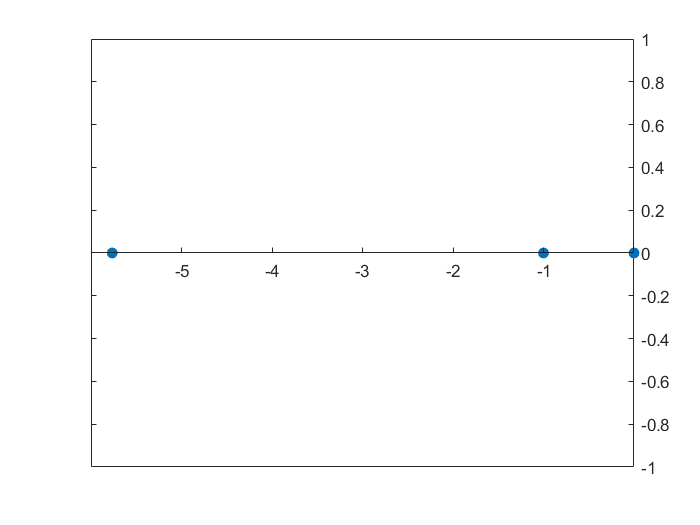


% Plot the poles 
stem(real(poles),imag(poles), 'filled')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Denoted by the blue dots are the poles of our system.

Having a pole at the origin makes the system critically stable.